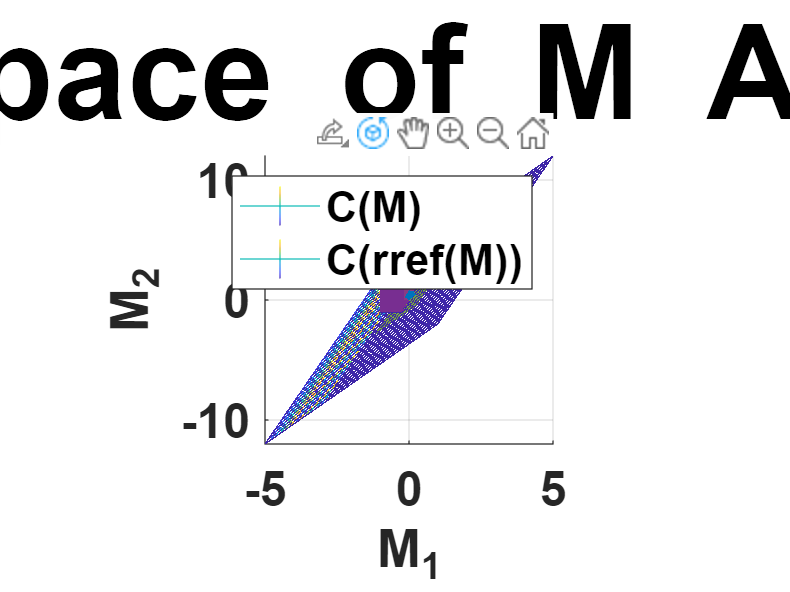

%% MATRIX SPACES B4 AND AFTER ROW REDUCTION:
clear ; clc ; 
% Create the Matrix: (matrix M)
M = [3,2 ; 5,7 ; 9,1] ; 
% And it's Row Reduced Form:
Mr = rref(M) ; 
% Now let's see how Columns Space of the matrix M changes after it's
% converted into it's rref form:
figure(14) ; clf ; hold on ; 
% ===================== Why This Code is Not working =================
% % 
funx1 = @(s,t) M(1,1)  *s  + M( 1,2)*t ; 
funx2 = @(s,t) Mr(1,1) *s  + Mr(1,2)*t ; 
funy1 = @(s,t) M(2,1)  *s  + M( 2,2)*t ; 
funy2 = @(s,t) Mr(2,1) *s  + Mr(2,2)*t ;
funz1 = @(s,t)  M(3,1) *s +  M( 3,2)*t ; 
funz3 = @(s,t) Mr(3,1) *s +  Mr(3,2)*t ;
h1 = fmesh( funx1 , funy1 , funz1  , repmat( [-1 1] , [1,2] )) ;
h2 = fmesh( funx2 , funy2 , funz3  , repmat( [-1 1] , [1,2] )) ;
% ============================================================================
% Draw the planes spaned by M and Mr :
h1 = fmesh( @(s,t) M(1,1)  *s  + M( 1,2)*t  , ...
            @(s,t) M(2,1)  *s  + M( 2,2)*t  , ...
            @(s,t)  M(3,1) *s +  M( 3,2)*t  , ...
            [-0.25 , 0.25] ) ; 
        
h2 = fmesh( @(s,t) Mr(1,1)  *s  + Mr( 1,2)*t  , ...
            @(s,t) Mr(2,1)  *s  + Mr( 2,2)*t  , ...
            @(s,t) Mr(3,1) *s   + Mr( 3,2)*t  , ...
            [-1 , 1] ) ; 
        
 
% Adjusting colors for Visiblity:
set(h1 , 'facecolor' , '#77AC30' , 'LineStyle' , 'none' , 'FaceAlpha' , 0.9 ) ; % green
set(h2 , 'facecolor' , [0.4940 0.1840 0.5560] , 'LineStyle' , 'none' , 'FaceAlpha' , 0.9 ) ; % violet
% Draw Normalized Basis Vectors:
N = M / norm(M) ; 
% Vectors to Plot: v1 - vector 1:
v1 = [ N(:,1)'  ; [0 0 0] ] ; 
v2 = [ N(:,2)'  ; [0 0 0] ] ;
v3 = [ Mr(:,1)' ; [0 0 0] ] ;
v4 = [ Mr(:,2)' ; [0 0 0] ] ;
% Default Blue Color
plot3( v1(:,1) , v1(:,2) , v1(:,3) , 'color' , [0 0.4470 0.7410]      , 'linew' , 4 ) ; 
plot3( v2(:,1) , v2(:,2) , v2(:,3) , 'color' , [0 0.4470 0.7410]      , 'linew' , 4 ) ; 
% Yellow Color
plot3( v3(:,1) , v3(:,2) , v3(:,3) , 'color' , '#EDB120' , 'linew' , 4 ) ; 
plot3( v4(:,1) , v4(:,2) , v4(:,3) , 'color' , '#EDB120' , 'linew' , 4 ) ; 
xlabel('M_1') ; ylabel('M_2') ; zlabel('M_3') ; 
axis square ; grid on ; rotate3d on ; 
set(gca , 'fontsize' , 18 , 'fontweight' , 'bold') ;
title('\fontsize{25} Column Space of M And rref(M) :')
legend({'C(M)';'C(rref(M))'})